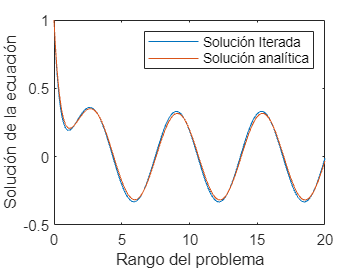

%Código creado por Nelson Bayona, estudiante de Ing
%Colombia 2022
%Por favor referenciar 

%¿QUE HACE EL CODIGO?
%Este código compara la solución diferencial con la
%solución analítica de una ecuación diferencial, con 
%a un  paso Ts{

%Declaro variables
syms y(x) 
Dy = diff(y);
a=1;
b=3;
c=2;
% Escribo la ecuación diferencial
ode = a*diff(y,x,2)+b*diff(y,x)+c*y == sin(x);
%Escribo las condiciones iniciales
ic=[Dy(0); y(0)]==[-2;1];
%soluciono la ecuacion diferencial con las CI
x=dsolve(ode,ic);
% paso diferencial
Ts=0.1;
%Rango de la función 
k = 0:Ts:20;
%Creación del vector de ceros con el tamaño del rango de k, es decir 201
z = zeros(size(k));
%Condición inicial y(0)=1
z(1) = 1; % z(1) significa el primer valor de y.
z(2) = 1+(-2) * Ts; %Segundo valor de y (y(2))
%Ciclo para calcular posteriores puntos
for i = 3:length(k) %desde tres hasta el tamaño de k
    z(i) = (-1)*(-2+(3*Ts)) * z(i-1) - (1+(-3*Ts)+(2*Ts^2)) * z(i-2) + Ts^2 * sin(Ts * (i-2));
end
plot(k, z) %graficar la solución iterada
hold on
fplot(x,[0,20]); %Graficar la solución analítica
hold off
xlabel('Rango del problema');
ylabel('Solución de la ecuación');
legend('Solución Iterada','Solución analítica');